clear

% Load point clouds
Rot_init = axang2rotm([1 0 0 pi/4]);
p_init = [1,-2,3]

p_init =      1    -2     3


points = [rand(1,50)'*10,rand(1,50)'*10,rand(1,50)'*10];
ptCloud1 = pointCloud(points);
ptCloud1.Color = "red"

ptCloud1 =   pointCloud with properties:

     Location: [50×3 double]
        Count: 50
      XLimits: [0.0401 9.9523]
      YLimits: [0.0050 9.7613]
      ZLimits: [0.3833 9.9455]
        Color: [50×3 uint8]
       Normal: []
    Intensity: []


% ptCloud2 = pointCloud(points*Rot_init);
ptCloud2 = pointCloud(points*Rot_init + p_init);
% ptCloud2 = pointCloud(points + p_init);
ptCloud2.Color = "blue"

ptCloud2 =   pointCloud with properties:

     Location: [50×3 double]
        Count: 50
      XLimits: [1.0401 10.9523]
      YLimits: [-0.8039 11.3893]
      ZLimits: [-2.8631 8.6961]
        Color: [50×3 uint8]
       Normal: []
    Intensity: []



% Initialize plot
figure;
subplot(2,1,1)
% h1 = pcshow(ptCloud1, 'MarkerSize', 25, "AxesVisibility","on");
h1 = scatter3(ptCloud1.Location(:,1), ptCloud1.Location(:,2), ptCloud1.Location(:,3));

hold on;
% h2 = pcshow(ptCloud2, 'MarkerSize', 25, "AxesVisibility","on");
h2 = scatter3(ptCloud2.Location(:,1), ptCloud2.Location(:,2), ptCloud2.Location(:,3));

title('ICP Registration');
legend('Point Cloud 1', 'Point Cloud 2');

maxIterations = 100;
rmse_target = 1e-1;
T = eye(4);
for i = 1:maxIterations
    % Find nearest neighbors
    %     idx = findNearestNeighbors(ptCloud1.Location, ptCloud2.Location);
    [idx, dist] = findNearestNeighbors(ptCloud1.Location, ptCloud2.Location);
    %     [idx, dist] = findNearestNeighbors(ptCloud1, ptCloud2);
    
    % Estimate transformation
    
    [R, p] = estimateTransform(ptCloud1.Location, ptCloud2.Location(idx,:));
    Tnew = eye(4);
    Tnew(1:3,1:3) = R;
    Tnew(1:3,4) = p;
    
%     Update transformation
    T = Tnew * T;
    ptCloud1 = pctransform(ptCloud1, rigidtform3d(R,p));
% ptCloud1 = pctransform(ptCloud1, affine3d(T));
    
    % Compute error
%     rmse = computeError(ptCloud1.Location, ptCloud2.Location, T);
    error = computeError(ptCloud1.Location, ptCloud2.Location);

    
    % Plot intermediate results
    set(h1, 'XData', ptCloud1.Location(:,1), 'YData', ptCloud1.Location(:,2), 'ZData', ptCloud1.Location(:,3));
    title(sprintf('ICP Registration (Iteration %d)\nError: %f', i, error));
    drawnow;
    
    % Check convergence
    if error < rmse_target
        disp("Convergence Reached")
        break
    end
end

Convergence Reached


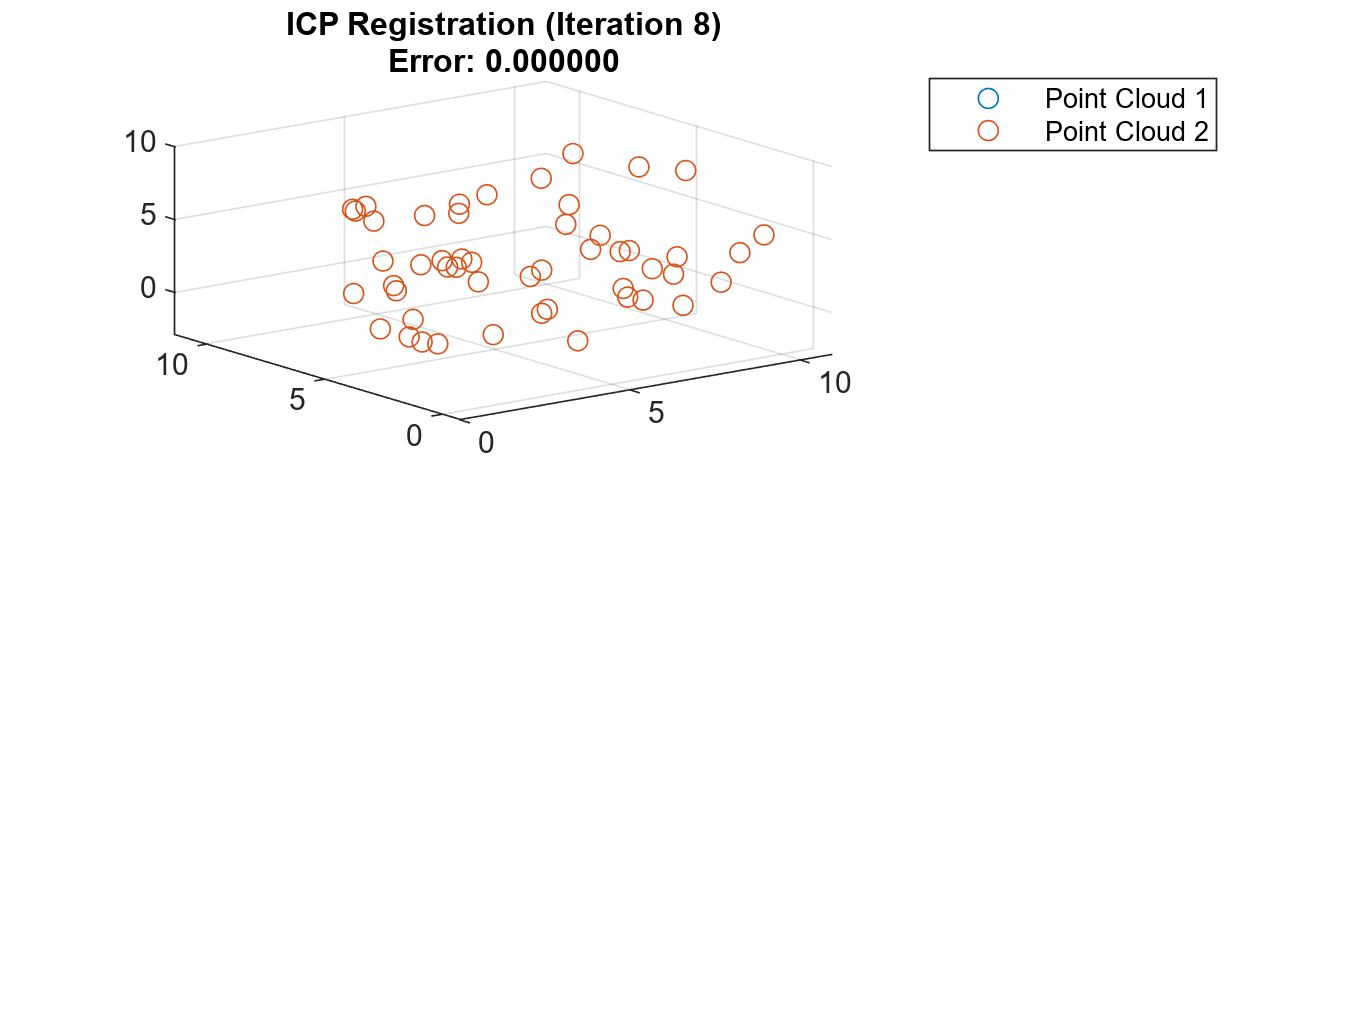


% Plot final result
set(h1, 'XData', ptCloud1.Location(:,1), 'YData', ptCloud1.Location(:,2), 'ZData', ptCloud1.Location(:,3));
title(sprintf('ICP Registration (Iteration %d)\nError: %f', i, error));

drawnow

% function [dist_index, dist_list] = findNearestNeighbors(ptCloud1, ptCloud2)
%     % Find nearest neighbors between two point clouds using KD-tree
%     tree = KDTreeSearcher(ptCloud2);
%     [dist_index, dist_list] = knnsearch(tree, ptCloud1);
% %------------------------------------------------------------------
% % function [dist_index, dist_list] = findNearestNeighbors(points_a, points_b)
% % dist_index = zeros(length(points_a), 1);
% % dist_list = zeros(length(points_a), 1);
% % for i = 1:length(points_a)
% %     shortest_distance = 100;
% %     a_i = points_a(i)';
% %     for j = 1:length(points_b) %for each sample point
% %           b_i = points_b(j)';
% %              dist = (norm(a_i - b_i));
% %         if dist < shortest_distance
% %             shortest_distance = dist;
% %             short_dist_index = j;
% %             dist_index(i) = short_dist_index';
% %               dist_list(i) = shortest_distance';
% %         end
% %     end
% %     
% % end
% end


function [dist_index, dist_list] = findNearestNeighbors(points_a, points_b)
    dist_matrix = pdist2(points_a, points_b);
    [dist_list, dist_index] = min(dist_matrix, [], 2);
end



function [R, t] = estimateTransform(ptCloud1, ptCloud2)
% Estimate rigid transform using SVD
X = ptCloud1;
Y = ptCloud2;
X_bar = mean(X);
Y_bar = mean(Y);
X_tilde = X - X_bar;
Y_tilde = Y - Y_bar;
H = (X_tilde' * Y_tilde)/(size(X, 1) - 1);
[U, ~, V] = svd(H); %U and V should be 3x3 matrices

tolerance = 1e-6;

if abs(det(U) * det(V) - 1) > tolerance
    [~, min_col] = min(abs(det(U) * U(:,1:2) * V(:,1:2)') - 1);
    U(:, min_col) = -U(:, min_col);
    R = V*U.';
% R = U*V.';
else
    R = V*U.';
% R = U*V.';
end

if abs(det(U) * det(V) + 1) < tolerance
    neg_last = [1,0,0;0,1,0;0,0,-1];
    R = (V*neg_last)*U.';
end

t = Y_bar' - R * X_bar';
end

% function [rmse, indices] = computeError(ptCloud1, ptCloud2, T)
%     % Transform ptCloud1 using T and compute RMSE
%     ptCloud1Transformed = (T * [ptCloud1'; ones(1, size(ptCloud1, 1))])';
%     ptCloud1Transformed = ptCloud1Transformed(:, 1:3);   
%     idx = findNearestNeighbors(ptCloud1Transformed, ptCloud2);
%     rmse = sqrt(mean(sum((ptCloud1Transformed - ptCloud2(idx, :)).^2, 2)));
%     indices = idx;
% end


% function rmse = computeError(ptCloud1, ptCloud2, T)
%     % Transform ptCloud1 using T and compute RMSE
%     ptCloud1Transformed = (T * [ptCloud1'; ones(1, size(ptCloud1, 1))])';
%     ptCloud1Transformed = ptCloud1Transformed(:, 1:3);
%     
%     % Find nearest neighbors between ptCloud1Transformed and ptCloud2
%     distances = pdist2(ptCloud1Transformed, ptCloud2);
%     [~, indices] = min(distances, [], 2);
%     
%     % Compute RMSE
%     errors = sqrt(sum((ptCloud1Transformed - ptCloud2(indices, :)).^2, 2));
%     rmse = sqrt(mean(errors.^2));
% end

function distance = computeError(ptCloud1, ptCloud2)
D = pdist2(ptCloud1,ptCloud2);
distance = mean(min(D,[],2))+mean(min(D,[],1));
end